load("SS_11_5.mat");

poles = [0.3 0.5 0.7];
if rank(ctrb(A,B)) == 3
    disp("System is controllable");
end

System is controllable


K = place(A,B,poles);

obs_poles = 0.6*poles;
L = place(A',C', obs_poles)';

x0 = [0; pi; 0];
N = 5/h;
xhat = zeros(3,N);
x = zeros(3,N);
u = zeros(1,N);
xhat0 = [0;pi;0];
xhat(:,1) = xhat0;

[x(:,1),y] = simSys(x0, 0, A, B, C, D);

for k = 2:N
    xhat(:,k) = A * xhat(:,k-1) + B * u(k-1) + L*(y - C * xhat(:,k-1));
    xhat(2,k) = mod(xhat(2,k), pi);
    u(k) = -K*(xhat(:,k) - [0; pi; 0]);
    u(k) = max(min(u(k), 1), -1);
    [x(:,k),y] = simSys(x(:,k-1), u(k), A, B, C, D);
end

t = h:h:5;
theta = x(2,:);

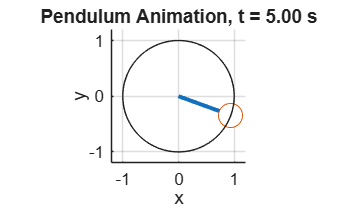

% Inputs required:
% t     = time vector
% theta = pendulum angle vector, in radians

t = t(:);
theta = theta(:);

Len = 1;              % pendulum length
origin = [0, 0];    % pivot point

x_point = Len*sin(theta);
y_point = -Len*cos(theta);

figure
axis equal
grid on
hold on

xlim([-1.2*Len 1.2*Len])
ylim([-1.2*Len 1.2*Len])

xlabel('x')
ylabel('y')
title('Pendulum Animation')

rod = plot([origin(1), x_point(1)], [origin(2), y_point(1)], 'LineWidth', 2);
bob = plot(x_point(1), y_point(1), 'o', 'MarkerSize', 12, 'MarkerFaceColor', 'auto');
trace = animatedline('LineWidth', 1);

for k = 1:length(t)
    set(rod, 'XData', [origin(1), x_point(k)], ...
        'YData', [origin(2), y_point(k)]);

    set(bob, 'XData', x_point(k), ...
        'YData', y_point(k));

    addpoints(trace, x_point(k), y_point(k));

    title(sprintf('Pendulum Animation, t = %.2f s', t(k)))
    drawnow

    if k < length(t)
        pause(t(k+1) - t(k))
    end
end